## GUMBEL DISTRIBUTION


$$\mu = 1, \beta=2$$


mu = 1;
beta = 2;
interval_begin = -50;
interval_end = 50;
number_of_partitions = 100000;

Gumbel Probability Density Function = $\frac{1}{\beta}exp\left(-\left(\frac{x-\mu}{\beta}+e^{-\left(\frac{x-\mu}{\beta}\right)}\right)\right)$

x = linspace(interval_begin, interval_end, number_of_partitions);
pdf = exp(-(((x-mu)./beta)+exp(-(x-mu)./beta))).*(1/beta); %gumbel PDF

Now to calculate Cumulative Distribution Function,

cdf = zeros(1, number_of_partitions);
for i = 2 : 1 : number_of_partitions
    cdf(1, i) = cdf(1, i-1) + ((interval_end-interval_begin)/number_of_partitions)*pdf(1, i-1);
end

Now plotting CDF and PDF,

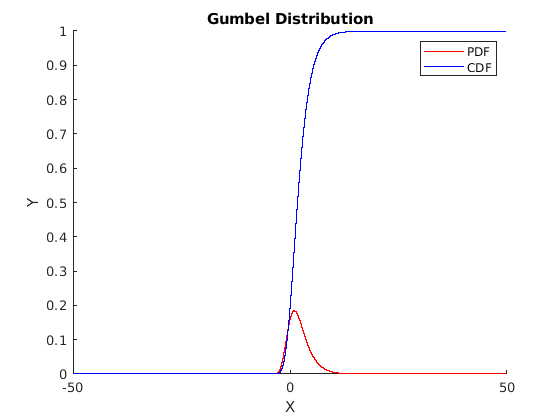

hold on;
plot(x, pdf, 'r');
plot(x, cdf, 'b');
legend(["PDF","CDF"]);
title("Gumbel Distribution");
xlabel("X");
ylabel("Y");
hold off;

To calculate variance by Reimann approximation,

Calculating the expectation value,


$$$$E[X]=\int_{-\infty}^{+\infty}xP(x)dx$$$$


expectation = 0;
for i = 2:1:number_of_partitions
    expectation = expectation + ((interval_end-interval_begin)/number_of_partitions).*pdf(1,i).*x(1,i);
end

Calculating the variance,


$$$$Var(X)=E[(X-E[X])^{2}]$$$$



$$$$Var(X)=\int_{-\infty}^{+\infty}(x-E[X])^{2}P(x)dx$$$$


variance = 0;
for i= 2:1:number_of_partitions
    variance= variance+ ((interval_end-interval_begin)/number_of_partitions).*pdf(1,i).*(x(1,i)-expectation).*(x(1,i)-expectation);
end

disp("By reimann approx. Variance = " + variance);

By reimann approx. Variance = 6.5797


Variance by analytical method = $\frac{\beta^{2}\pi^{2}}{6}$

disp("Analytically variance = " + beta*beta*pi*pi/6);

Analytically variance = 6.5797
